%画出Ryy
ny = 7000;
Ryy_y3 = conv(y3, flipud(y3))

Ryy_y3 = 1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


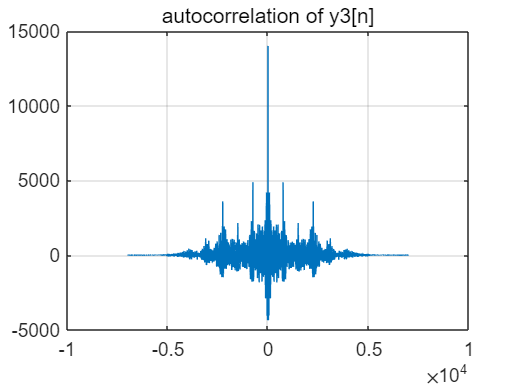

figure(1);
plot(-ny+1 : ny - 1, Ryy_y3);
grid on;
title('autocorrelation of y3[n]')

%通过Ryy得到N1 = 750, N2 = 2250
N1 = 750;
N2 = 2250;
Ryy = conv(z, flipud(z));

%遍历找best_alpha1
mini_norm = 100000;
best_alpha1 = 0;
for i = 1 : 9
    tic;
    alpha1 = 0.1 * i
    x_temp = filter(1, [1, zeros(1, N1-1), alpha1], y3);
    Rxx_temp = conv(x_temp, flipud(x_temp)).';
    Ryy_temp = (1 + alpha1^2) * Rxx_temp + alpha1 * [zeros(1, N1), Rxx_temp(1 : 2 * ny - 1 - N1)] + alpha1 * [Rxx_temp(N1+1 : 2*ny-1), zeros(1, N1)];
    error = Ryy - Ryy_temp;
    if norm(error, 2) < mini_norm
        mini_norm = norm(error, 2);
        best_alpha1 = alpha1;
    end
    toc;
end

%遍历找best_alpha2
mini_norm = 100000;
best_alpha2 = 0;
for i = 1 : 9
    tic;
    alpha2 = 0.1 * i
    x_temp = filter(1, [1, zeros(1, N2-1), alpha2], y3);
    Rxx_temp = conv(x_temp, flipud(x_temp)).';
    Ryy_temp = (1 + alpha2^2) * Rxx_temp + alpha2 * [zeros(1, N2), Rxx_temp(1 : 2 * ny - 1 - N2)] + alpha2 * [Rxx_temp(N2+1 : 2*ny-1), zeros(1, N2)];
    error = Ryy - Ryy_temp;
    if norm(error, 2) < mini_norm
        mini_norm = norm(error, 2);
        best_alpha2 = alpha2;
    end
    toc;
end

a_y3 = [1, zeros(1, N1 - 1), best_alpha1, zeros(1, N2 - N1 - 1)];
x3 = filter(1, a_y3, y3); %去噪y3
sound(x3)
Rxx_x3 = conv(x3, flipud(x3));

figure(2);
subplot(2, 1, 1);
plot(-ny+1 : ny-1, Rxx_x3);
grid on;
title('autocorrelation of y3[n] without echo')

subplot(2, 1, 2);
plot(ny, x3);
grid on;
title('y3[n] without echo')

